# Interpolation Using Splines

Interpolation to determine unknown values between known points is a standard tool for engineers and scientists. Interpolation by splines is one common method of determining a continuous function through discrete data. There are many different algorithms for determining a spline that allow you to preserve various properties such as smoothness or curvature. All splines pass directly through the known datapoints. 

Interpolation between known values can provide a practical, scalable, and controllable way to describe a continuous function while preserving chosen properties. 

## What is interpolation?

The digital world consists of a vast amount of discrete data. Each digital sensor records discrete datapoints. In some cases, datapoints may be very close together, such as a high-speed video sampled at 240 frames per second. In other cases, the datapoints may be much farther apart, such as the spatial locations of weather stations or your height and weight records from annual physicals in time. However, the exact value that you want to determine may not be in the data set at all. Interpolation is creating a function between known values that you can utilize to approximate values at additional points. 

#### Example: Solar Power Generation data

In this example, you will compare several different interpolation and regression models. You should be able to see the distinctions between an interpolated curve, which is required to pass through every known point, and a regression model that attempts to minimize the error to every point but may not pass directly through any of them. 

Run this code to compare four interpolation models and three regression models applied to solar power generation data. 

% Local function, details in Helper Functions
[xTrain,yTrain,xTest,yTest] = setUpData("SolarPowerGeneration.csv");

% From the Curve Fitting Toolbox, generate a chosen type of fit to the data
[fitResult,gof] = fit(xTrain,yTrain,"sin8","Normalize","on");

% Local function, details in Helper Functions
presentFittedResults(fitResult,gof,xTrain,yTrain,xTest,yTest)

  **Pro-tip**. If you want to interactively explore modeling options for this data, you can open the Curve Fitter app by uncommenting and running the next line of code. You can find additional information in the documentation for [`curveFitter`](https://www.mathworks.com/help/curvefit/curvefitter-app.html). 

% curveFitter(xTrain,yTrain)

  **Try**.

- Change the type of model to a different interpolation model using the dropdown. What do you observe about the fit, error, $r^2$ and residual plot in each case?

- Change the type of model to different regression models using the dropdown. What do you observe about the fit, error, $r^2$ and residual plot in each case?

  **Pro-tip**. You can interactively modify the plot, e.g., move the legend or zoom in if you use the arrow that appears if you hover over the plots to open a separate figure window.

Interpolation, from roots meaning *between* and *polishing*, is a mathematical method of assigning values to additional data using information from a set of discrete data. Some interpolation methods include Gaussian processes (kriging), [Fourier series analysis](https://github.com/MathWorks-Teaching-Resources/Fourier-Analysis), and splines. As you saw with the solar power generation data, we can use interpolation to create a more continuous representation of the system for study or estimate a value between measured values. Because interpolants must pass through the known datapoints, the error will be 0 on the original set. Subdividing your data into a training set and a testing set can help you get a more realistic estimate of error. This script will discuss spline methods for interpolation. 

### What is a spline?

A mathematical spline is a continuous interpolation built from low degree polynomials that passes through every data point of some functional data, such as a time series. Outside of mathematics, a classic spline was a thin, flexible physical object that a designer could fasten at control points to generate a physically-realized smooth curve through the control points. 

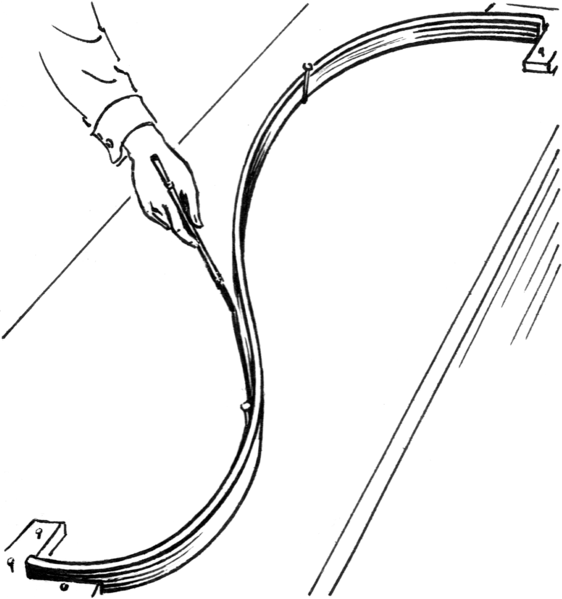

Credit: [Pearson Scott Foresman](https://en.wikipedia.org/wiki/Flat_spline#/media/File:Spline_(PSF).png) from the Wikimedia Commons

### Interpolation and regression apply to different types of problems

Interpolation fixes the specific values of known data. This can allow for simple methods of interpolation that may be practical by hand. Regression attempts to capture the essence of a data set rather than the specifics. Regression is appropriate when the data are noisy or error-prone, especially if you have many data points.

### How does extrapolation differ from interpolation?

Interpolation only applies to values inside the convex hull defined by known values. For interpolation in time, you can only interpolate for times between the earliest measurement and the latest measurement in your data set. For interpolation in temperature, you can only interpolate between the lowest temperature and the highest temperature in your dataset. If you want to use the function you have created outside that range of values, you are moving into extrapolation. Extrapolation is the estimation of unknown values outside of a set of known values in a logical way. 

Interpolated values are computed with reference to control points from multiple directions. Because extrapolated values are unbounded, there can be cases where logical assumptions lead to entirely incorrect estimates. Consider trying to extrapolate the conductivity of a superconducting element from datapoints measured above its critical temperature. 

## Tradeoffs between memory, computational time, and detail

While it may be tempting to collect more data, it is important to remember that even if we ignore the expense of data collection, additional data will require more storage space in memory and more computational time to build a general interpolation function. That said, if there are too few datapoints, the detail of your interpolated result will suffer.

###  Collect data to study

Let's begin by defining a dataset to use throughout this script.

% hand.mlx will walk you through collecting data in hand.mat and
% drawing.mat to use for the rest of this script
open hand.mlx

## Linear Splines

The simplest form of a one-dimensional spline is a piecewise linear function. Beginning with a dataset consisting of $n$ points: 

$\left\{(x_1,y_1),(x_2,y_2),\ldots,(x_i,y_i),\ldots,(x_n,y_n)\right\}$,

 the piecewise linear function $S(x)$ is the function that connects the dots.


$$S(x) = \begin{cases} y_1 + \left(\frac{y_2-y_1}{x_2-x_1}\right)x & x_1 \leq x < x_2 \\ y_2 +  \left(\frac{y_3-y_2}{x_3-x_2}\right)x & x_2 \leq x < x_3 \\ \vdots \\ y_i +  \left(\frac{y_{i+1}-y_i}{x_{i+1}-x_{i}}\right)x & x_i \leq x < x_{i+1} \\ \vdots \\ y_{n-1} +  \left(\frac{y_n-y_{n-1}}{x_n-x_{n-1}}\right)x & x_{n-1} \leq x < x_n \\ y_n & x = x_n \end{cases}$$


% Run this code to visualize the piecewise linear interpolation of your
% data
clear
% Load the data you collected using hand.mlx, which includes
% variables x and y
load hand2.mat
% Construct a figure
figure
% Plot the known datapoints
plot(x,y,"k.","MarkerSize",10)
% On the same plot, add the piecewise linear approximation
hold on
plot(x,y)
hold off

 **Reflect**.

- Does your piecewise linear spline capture your data sufficiently well? Why? If not, please go [back](matlab: edit hand.mlx) and collect a new data set that you are satisfied with. 

- How complicated is the piecewise linear interpolation? Could you create it by hand?

- What will happen to your piecewise linear interpolation if you add or remove datapoints?

** Exercise 1**.

Write a function `linInterp(xData,yData,xNew)` where `xData` and `yData` are vectors of the known x- and y-coordinates that uses piecewise linear interpolation to calculate `yNew` from the vector `xNew`. You may assume that `xData` is strictly increasing or strictly decreasing and that `xData` and `yData` are both the same size.

% Open a template function linInterp.m
open linInterp.m

% Test your linInterp.m function here
[errors,out] = testLinInterpCode(@linInterp);

###   Varying Data by Adding Datapoints

Adding data points will increase the resolution, but that involves collecting additional data somehow. While this applies in some real-life situations, there are many occasions where you are not in control of the data collection, and you must work with the data that exists. If you randomly add a data point, even a linear interpolant can change drastically but only in a local region.

% %% This code assumes you have data sets x and y from hand2.mat
% %% or a self-created data set loaded in your workspace.
%
% Construct a figure
figure
% Plot the known datapoints
plot(x,y,".","MarkerSize",10,"SeriesIndex",1)
% On the same plot, add the piecewise linear approximation
hold on
plot(x,y)
% Randomly generate a point in the correct domain and range
xAdd = min(x)+rand(1)*(max(x)-min(x));
yAdd = min(y)+rand(1)*(max(y)-min(y));
plot(xAdd,yAdd,"+","MarkerFaceColor","auto","MarkerSize",7,"SeriesIndex",5,"LineWidth",3)
% Insert the new point at a random point in the dataset
addIdx = randi(length(x)+1);
xAll = [x(1:addIdx-1);xAdd;x(addIdx:end)];
yAll = [y(1:addIdx-1);yAdd;y(addIdx:end)];
plot(xAll,yAll)
hold off
% Add a legend to identify each new component of the figure
legend(["" "" "Random Point" "New Interpolation"],...
    "Location","best")

###   Varying Data by Removing Datapoints

Removing data points is one method of compressing your data into a smaller size for storage or transport. It does lose information, but depending on your dataset and method of interpolation, this may or may not impact your result. Use the provided sliders to step over several points at once by changing `stepSize.`

% This code checks that you have data sets x and y from hand2.mat
% or a self-created data set such as hand.mat or drawing.mat
% loaded in your workspace, if not it loads hand2.mat
if ~exist("x","var") || ~exist("y","var")
    load hand2.mat
end

% Set up values to control the options on the sliders:
xLength = length(x);
stepMax = floor(xLength/2);
stepDefault = ceil(xLength/10);

% Construct a figure
figure
% Plot the known datapoints
plot(x,y,".","MarkerSize",10,"SeriesIndex",1)
% On the same plot, add the piecewise linear approximation
hold on
plot(x,y,"SeriesIndex",1)
% Increase the step size to use fewer points from the data set
stepSize = 5;
plot(x(1:stepSize:end),y(1:stepSize:end),"-","LineWidth",2,"SeriesIndex",2)
hold off

In this section, skip exactly one datapoint by changing `skip`.

% Construct a figure
figure

% Plot the known datapoints
plot(x,y,".","MarkerSize",10,"SeriesIndex",1)

% On the same plot, add the piecewise linear approximation
hold on
plot(x,y,"SeriesIndex",1,"LineWidth",3)

% Set up values to control the options on the sliders:
[~,skipDefault] = max((diff(y)).^2+(diff([0; y(1:end-1)])).^2);

% Set the value of skip to remove any one datapoint
skip = 10;
plot(x([1:skip-1 skip+1:end]),y([1:skip-1 skip+1:end]),"-","LineWidth",2,"SeriesIndex",3)
plot(x(skip),y(skip),"SeriesIndex",2,"Marker","x","MarkerSize",10,"LineWidth",3)
hold off

Or you can remove an interval of datapoints:

% Construct a figure
figure

% Plot the known datapoints
plot(x,y,".","MarkerSize",10,"SeriesIndex",1)

% On the same plot, add the piecewise linear approximation
hold on
plot(x,y,"SeriesIndex",1,"LineWidth",3)

% Set up values to control the options on the sliders:
startDefault = min(max(2,skipDefault),stepDefault);
stopDefault = max(stepDefault,min(skipDefault,xLength));

% Set the value of skip to remove any one datapoint
start = 5;    stop = 12;
plot(x([1:start-1 stop:end]),y([1:start-1 stop:end]),"-","LineWidth",2,"SeriesIndex",3)
plot(x(start:stop-1),y(start:stop-1),"SeriesIndex",2,"Marker","x","MarkerSize",10,"LineWidth",3)
hold off

## Cubic Splines

A cubic spline uses additional points to preserve more information about the curve. There are different cubic splines, but each one is fundamentally using several datapoints to answer the same question. What coefficients $a_i$ are needed in 


$$y = a_0 + a_1x + a_2x^2+a_3x^3$$


so that each known data point is a solution to this equation? 

Specifically, if we have a dataset consisting of $n$ pairs of points, $\left\{(x_1,y_1),(x_2,y_2),\ldots,(x_i,y_i),\ldots,(x_n,y_n)\right\}$, then there are $n-1$ cubic equations describing the spline.


$$S(x) = \begin{cases} S_1(x) = a_{01} + a_{11}x + a_{21}x^2+a_{31}x^3 & x_1 \leq x < x_2 \\ S_2(x) = a_{02} + a_{12}x + a_{22}x^2+a_{32}x^3 & x_2 \leq x < x_3\\ \vdots  \\ S_i(x) = a_{0i}+a_{1i}x+a_{2i}x^2+a_{3i}x^3 & x_i\leq x < x_{i+1} \\ \vdots \\ S_{n-1}(x) = a_{0(n-1)} + a_{1(n-1)}x + a_{2(n-1)}x^2+a_{3(n-1)}x^3 & x_{n-1} \leq x < x_n \\ y_n & x = x_n \end{cases} \;\;\;\;\;\;\; (\Delta)$$


The challenge is to determine the values of the coefficients $a_{ij}$. There are only $n-1$ conditions $S_k(x_k) = y_k$ and $n-1$ conditions $S_k(x_{k+1}) = y_{k+1}$, while there are $4(n-1) = 4n-4$ unknowns. 

#### Example: Two Different Spline Interpolations 

The data file `car.mat` contains the variables `xCar` and `yCar` that present a rough sketch of a car. 

% Load a new data set to demonstrate the differences between different
% cubic spline methods
load car.mat

% Method 1
n = length(xCar);
s = (1:n)';
t = (1:0.05:n)';
u = spline(s,xCar,t);
v = spline(s,yCar,t);
plot(u,v)

% Method 2
u2 = pchip(s,xCar,t);
v2 = pchip(s,yCar,t);
hold on
plot(u2,v2)
hold off

% Add original points
hold on
plot(xCar,yCar,"*","SeriesIndex",4,"MarkerSize",8,"LineWidth",3)
hold off

% Label the figure
title("A rough sketch of a car")
legend(["spline","pchip","control points"])

With this data, the `spline` curve does a more elegant job of drawing in a curvy chassis, but the spline-drawn wheels look a bit impractical. On the other hand, the `pchip` interpolation does not overshoot values in the same way as `spline`, so the wheels look better, but the chassis is very blocky. 

As you can see, the same exact data is being interpolated slightly differently by these two methods, but both of them are "curvier" than the piecewise linear approximation. By replacing `car.mat` with the name of your own data set such as `hand.mat` or `drawing.mat` and updating the variable names appropriately, you can investigate other examples as well. 

### Hermite Interpolation

Hermite interpolants use one approach. In this case, we require that both the endpoint values and the first derivatives of the functions must be continuous, $S'(x_k)=d_k$. We don't know the value of $d_k$, but we can estimate it in terms of values that we do know.

Let's define a few new expressions. While we do not know the values of the $d_k$, we can use the method of divided differences to estimate them. The first divided difference is the slope of the linear piecewise interpolation in the $k^{\text{th}}$ interval. Let's denote this $m_k = \frac{y_{k+1}-y_{k}}{{x_{k+1}-x_{k}}$. Let's define the length of the $k^{\text{th}}$ interval to be $h_k = x_{k+1}-x_k$. The interpolation function will also be slightly simpler to express if we use local coordinates, $s_k = x-x_k$, tracking how far we have moved from the initial point, $x_k$, of the $k^{\text{th}}$ interval. 


$$S_k(x) = \frac{3h_ks_k^2-2s_k^3}{h_k^3}y_{k+1} + \frac{h_k^3-3h_ks_k^2+2s_k^3}{h_k^3}y_k + \frac{s_k^2(s_k-h_k)}{h_k^2}d_{k+1} + \frac{s_k(s_k-h_k)^2}{h_k^2}d_k \;\;\;\;\;\;\; (\star)$$


Observe that  $S_k(x_k) = \frac{3h_k0^2-2(0^3)}{h_k^3}y_{k+1} + \frac{h_k^3-3h_k0^2+2(0^3)}{h_k^3}y_k + \frac{0^2(0-h_k)}{h_k^2}d_{k+1} + \frac{0(0-h_k)^2}{h_k^2}d_k = y_k$, because $s_k(x_k)=0$. 

**Exercise 2**

- Check that $S_k(x_{k+1}) = y_{k+1}$.

- Check that $S_k'(x_{k}) = d_k$.

- Check that $S_k'(x_{k+1}) = d_{k+1}$.

- Explain why the expressions for $S_k(x)$ in equation $(\star)$ and equation $(\Delta)$ are equivalent.  

### Method 1: Require a continuous second derivative

If we require $S(x)$ to have a continuous second derivative, that means that we have to require that

 $\lim_{x\to x_k^+} S_k''(x) =  \lim_{x\to x_k^-}S_{k-1}''(x)$. 

**Exercise 3**

a) Express the condition $\lim_{x\to x_k^+} S_k''(x) =  \lim_{x\to x_k^-}S_{k-1}''(x)$ using $s = x-x_k$, $h_k$, $h_{k-1}$, $y_{k-1}$, $y_{k}$, and $y_{k+1}$ as in equation $(\star)$. Hint: Remember that $x_k = x_{k-1}+h_{k-1}$ as well.

b) Are there any values of $k$ where you cannot use the condition presented in Exercise 3, part a)? Why or why not?

#### A Piecewise Cubic Spline Formula

We can reorganize the results from Exercise 3 so that $Ad = r$, where $d = \pmatrix{d_1 \cr d_2 \cr d_3 \cr \vdots \cr d_n}$ and $A = \pmatrix{h_2 & h_2+h_1 & & & & \cr h_2 & 2(h_1+h_2) & h_1 & & & \cr & h_3 & 2(h_2+h_3) & h_2 & & \cr && \ddots & \ddots & \ddots & \cr &&& h_{n-1} & 2(h_{n-2}+h_{n-1}) & h_{n-2} \cr &&&&h_{n-1}+h_{n-2} & h_{n-2}}$. The right-hand side is $r = 3\pmatrix{r_1 \cr h_2m_1+h_1m_2 \cr h_3m_2+h_2m_3\cr \vdots \cr h_{n-1}m_{n-2}+h_{n-2}m_{n-1} \cr r_n}$. We can use the first two intervals together to generate a cubic equation to calculate that $r_1 = \frac{5}{6}m_1 + \frac{1}{6}m_2$ and $r_n = \frac{1}{6}m_{n-2}+\frac{5}{6}m_{n-1}$. 

** Exercise 4**.

Implement the algorithm described by the piecewise cubic spline formula. 

% Open a template function called pcSpline.m
open pcSpline.m

% % Uncomment this section of code to test your result on the car data
% 
% [uMine,dxMine] = pcSpline(s,x,t);
% [vMine,dyMine] = pcSpline(s,y,t);
% u = spline(s,x,t);
% v = spline(s,y,t);
% plot(uMine,vMine)
% hold on
% plot(x,y,"*")
% plot(u,v)
% hold off

## Method 2: Preserve the shape

While the piecewise cubic spline can overshoot values

** Exercise 5**.

Implement the algorithm described by the shape-preserving piecewise cubic Hermite interpolation formula. 

% Open a template function called pcHInterp.m
open pcHInterp.m

% % Uncomment this section of code to test your result on the car data
% [u2Mine,d2x] = pcHInterp(s,x,t);
% [v2Mine,d2y] = pcHInterp(s,y,t);
% u2 = pchip(s,x,t);
% v2 = pchip(s,y,t);
% plot(u2Mine,v2Mine)
% hold on
% plot(x,y,"*")
% plot(u2,v2)
% hold off

### Other Splines

There are other types of splines--you might have noticed that we skipped quadratic splines in this discussion--as well as generalizations to higher-dimensional surfaces. However, the splines most common in practice are cubic, and all follow the basic structural constraints we've discussed with varying choices about what additional constraints to enforce.

## Helper Functions

function [errors,out] = testLinInterpCode(linInterp)
% TESTLININTERPCODE runs linInterp on several sets of test data
%
% ERRORS collects the errors for each test
% OUT is a boolean tracking success or failure of all tests
errors = nan([1,3]);

% Test 1
try
    disp("Running test 1...")
    tol = 1e-15;
    rVal = rand(1)*4+1;
    if rVal <= 3
        Fexpected = 4*(rVal-1)+1;
    else
        Fexpected = 8*(rVal-3)+9;
    end
    Fapprox = linInterp([1 3 5],[1 9 25],rVal);
    errors(1) = Fexpected-Fapprox;
    assert(abs(Fexpected-Fapprox)<tol,"Failed Test 1.")

    % Test 2
    disp("Running test 2...")
    tol = 1e-14;
    f = @(x)1.6*x.^3-4*x.^2-5;
    xVals = -12:3:6;
    fVals = f(xVals);
    rVals = rand(1)*3+xVals(1:end-1);
    Fexpected = (fVals(2:end)-fVals(1:end-1))/3.*(rVals-xVals(1:end-1))+fVals(1:end-1);
    Fapprox = linInterp(xVals,fVals,rVals);
    errors(2) = prod(abs(Fexpected - Fapprox) < tol);
    assert(prod(abs(Fexpected-Fapprox)<tol),"Failed Test 2.")

    % Test 3
    disp("Running test 3...")
    tol = 1e-16;
    f = @(x) cos(x);
    xVals = 0:-1:-6;
    fVals = f(xVals);
    rVals = -rand(1)+xVals(1:end-1);
    Fexpected = (fVals(1:end-1)-fVals(2:end)).*(rVals-xVals(1:end-1))+fVals(1:end-1);
    Fapprox = linInterp(xVals,fVals,rVals);
    errors(3) = prod(abs(Fexpected - Fapprox) < tol);
    assert(prod(abs(Fexpected-Fapprox)<tol),"Failed Test 3.")

    out = 1;
    disp("All tests passed.")
catch
    out = 0;
    disp("Please update your linInterp code and try again.")
end
end

function [xTrain,yTrain,xTest,yTest] = setUpData(filename)
% SETUPDATA uses tools from the Statistics and Machine Learning Toolbox
% to split data into a test data set and a training data set
data = readtable(filename);
data.Properties.VariableNames = {'varX' 'varY'};
if class(data.varX(1))=='datetime' %#ok<BDSCA>
    data.varX = hours(data.varX-data.varX(1));
end
num = length(data.varX);
sIdx = ceil(num*3/7);
dataX = data.varX(sIdx:end);
dataY = data.varY(sIdx:end);
c = cvpartition(length(dataX),"HoldOut",.3);
idxTrain = training(c);
idxTest = test(c);
xTrain = dataX(idxTrain);
yTrain = dataY(idxTrain);
xTest = dataX(idxTest);
yTest = dataY(idxTest);
end

function presentFittedResults(fitResult,gof,xTrain,yTrain,xTest,yTest)
% PRESENTFITTEDRESULTS takes a trained model with goodness-of-fit
% information and testing and training data sets and presents the results
if gof.sse==0
    disp("This is an interpolation model.")
else
    disp("This is a regression model.")
end

residual = yTest - fitResult(xTest);
sse = norm( residual )^2;
rmse = sqrt( sse/length( residual ) );

disp("This model has an SSE of "+gof.sse+" and an r^2 of "+gof.rsquare+".")
disp("The validation set has an RMSE of "+rmse+".")

% Create a figure for the plots.
figure('Name','Fitted Curve');

% Plot fit with data.
subplot( 2, 1, 1 );
h = plot(fitResult,xTrain,yTrain,'.');
% Add validation data to plot.
hold on
h(end+1) = plot(xTest,yTest,'.');
hold off
legend(h,'yTrain vs. xTrain','Fitted Curve','yTest vs. xTest','Location','bestoutside','Interpreter','none');
% Label axes
xlabel( 'xTrain', 'Interpreter', 'none' );
ylabel( 'yTrain', 'Interpreter', 'none' );
grid on

% Plot residuals.
subplot( 2, 1, 2 );
h = plot(fitResult,xTrain,yTrain,'residuals');
% Add validation data to plot.
hold on
h(end+1) = plot(xTest,yTest - fitResult(xTest),'bo','MarkerFaceColor','w');
hold off
legend(h, 'Residuals', 'Zero Line', 'Validation Residuals', 'Location', 'bestoutside', 'Interpreter', 'none' );
% Label axes
xlabel('xTrain','Interpreter','none');
ylabel('yTrain','Interpreter','none');
grid on
end